## DATA 604 - HW1

### Name: Precious Worgu

### Student ID: 119343890

### 1) Loading the USPS Handwritten Digits data set

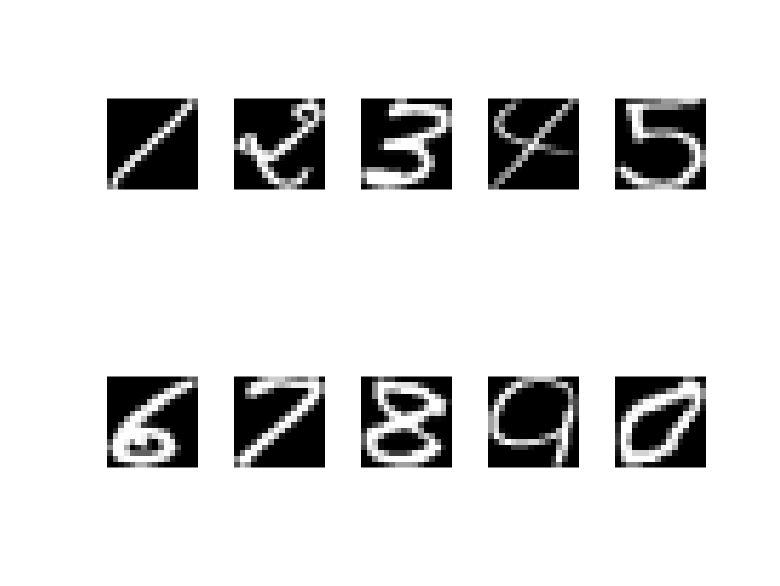

% Loading the dataset
load('usps_all.mat');

% Get the images
images = data;

% Set the number of rows and columns in the grid
numRows = 2;
numCols = 5;

% Create a new figure window
figure(1);

% Create a new subplot for each image
for i=1:numRows*numCols
    subplot(numRows, numCols, i);
    imshow(reshape(images(:,5, i), 16, 16));
end

### 2) Finding the sample mean for each set of 1100 digit examples

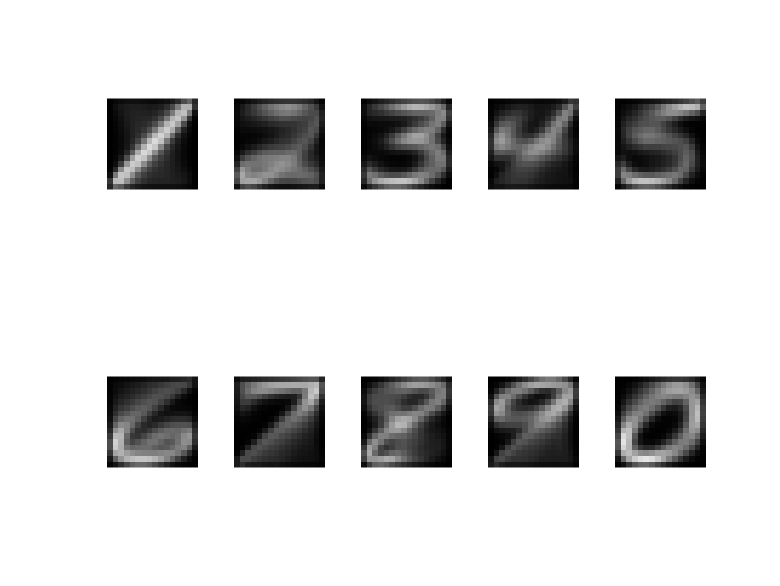

y = zeros(256, 1100, 10);

figure(2);
% Calculate the sample mean for each set of 1100 digits
for i = 1:10
    X = data(:,:,i);
    xsize = size(X);
    y(:,i) = sum(X, 2)/xsize(2);
    means(:,i) = uint8(y(:,i));

    % Plot the averages on a 2x5 grid
    subplot(2,5,i);
    imshow(reshape(means(:,i), 16,16, []));
end

### 3) Sample mean for all 10 full sets of handwritten digit examples

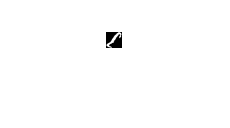

% Calculate the mean
y= data(:,i);
ysize = size(y);
mean = sum(y, 2)/ysize(2);
mean = uint8(mean);

% Plot the mean
figure;
imshow(reshape(mean, 16, 16, []));

### 4)

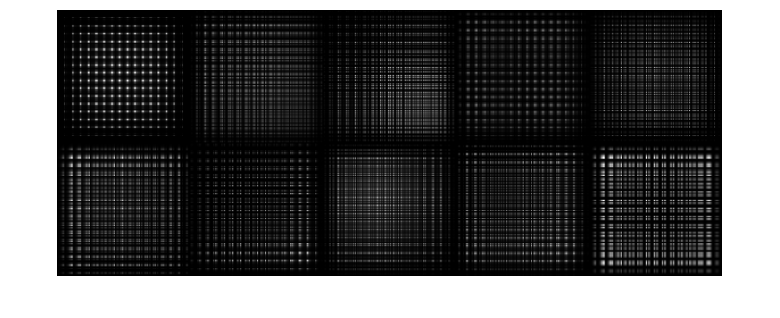

covMatrix(data);

function grid=covMatrix (x)
    r=2; c=5; s=256;
    grid(r*s,c*s)=0;
    for i = 1:r
        for j=1:c
            d=x(:,:,5*(i-1)+j);
            dsize = size(d);
            dbar = sum(d, 2)/dsize(2);
            dbar = double(dbar);
            Q = zeros(dsize(1));
            for k = 1:dsize(2) 
                difvec = im2double(d(:,k)) - dbar;
                Qtest = difvec*difvec.';
                Q = Q+ Qtest;
            end
            Q = Q/(dsize(2)-1);
            grid((i-1)*s+1:i*s,(j-1)*s+1:j*s)=Q;
        end
    end
    figure;
    imshow(grid,[]);
end

### 5) 

**The multivariate normal distribution** is used to model each single integer class of the USPS digit image dataset. The model consists of a mean vector with 10 components, each representing the class of a digit (0-9). The multivariate normal distribution for the ith digit class can be written as:

N(mean, cov)

**Computation Complexity**

The USPS data contains:

﻿﻿10 digit classes

﻿﻿1100 images per class

﻿﻿Each image is represented as a 256-dimensional vector of 8-bit grayscale values

To estimate the parameters of the multivariate normal distribution for each class, we need to compute the sample mean and sample covariance matrix, which involve computing sums of pixel values and pixel value products, respectively.

Therefore, the computational cost for computing these distributions would scale with the number of dimensions (256) and the number of training points (1100) per class, resulting in a total computational cost of 256 x 256 x 1100 x 10 ~7 billion computations.